# **Standing wave dispersion simulation **

clear
clc

`현재 위치 설정 및 경로추가

cd 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 2.0 - 20250604_asym_IR'
addpath 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 2.0\data'

랜덤 방식 설정

rng('shuffle'); % Seed the random number generator based on the current time

% w0_list = [2.5:2.5:30]

j_list = [0 2 2 2]

j_list =      0     2     2     2


m_list = [0 0 1 2]

m_list =      0     0     1     2


for q_ind = 1:4
vx_tilt_list = [9.5]
for tilt_ind = 1:numel(vx_tilt_list)

vx_tilt_list = 9.5000

vx_tilt_list = 9.5000

vx_tilt_list = 9.5000

vx_tilt_list = 9.5000

기본 상수 설정

load("STN_constants.mat"); %load default constants
%you can re-define contants here, for example 
MAX=2e4
%tau=
%lambda=
% w0=24e-6
vx_caused_tilted=vx_tilt_list(tilt_ind)
j_num=j_list(q_ind);
m_num=m_list(q_ind);
w0z=26.33e-6 
w0y=22.52e-6 
Dye_sigma = 4.8e-6

MAX = 20000

vx_caused_tilted = 9.5000

w0z = 2.6330e-05

w0y = 2.2520e-05

Dye_sigma = 4.8000e-06

MAX = 20000

vx_caused_tilted = 9.5000

w0z = 2.6330e-05

w0y = 2.2520e-05

Dye_sigma = 4.8000e-06

MAX = 20000

vx_caused_tilted = 9.5000

w0z = 2.6330e-05

w0y = 2.2520e-05

Dye_sigma = 4.8000e-06

MAX = 20000

vx_caused_tilted = 9.5000

w0z = 2.6330e-05

w0y = 2.2520e-05

Dye_sigma = 4.8000e-06

세기(I) 리스트 작성

%I1, I2 setting (I1과 I2의 행렬 크기를 같게 하세요.)

I1_list=[0, 1.8, 3.2, 5.0, 7.2, 9.8, 12.8, 14.4, 16.2, 20.0, 24.2, 28.8, 33.8, 39.2, 45.0, 61.3, 80.1]
I2_list=ones(numel(I1_list),1)'*0.2

% I1_list=[0, 0.6, 0.8, 1, 1.2, 1.4, 1.6, 1.8, 2, 2.2, 2.4, 2.6, 2.8, 3, 3.5, 4, 4.5, 5];
% I2_list=I1_list;
% I1_list=[2];
% I2_list=I1_list;
Cell_velocity=cell(numel(I2_list),1);
Cell_alpha=cell(numel(I2_list),1);
Cell_x_matrix=cell(numel(I2_list),1);
Cell_y_matrix=cell(numel(I2_list),1);

I1_list =          0    1.8000    3.2000    5.0000    7.2000    9.8000   12.8000   14.4000   16.2000   20.0000   24.2000   28.8000   33.8000   39.2000   45.0000   61.3000   80.1000


I2_list =     0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000


I1_list =          0    1.8000    3.2000    5.0000    7.2000    9.8000   12.8000   14.4000   16.2000   20.0000   24.2000   28.8000   33.8000   39.2000   45.0000   61.3000   80.1000


I2_list =     0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000


I1_list =          0    1.8000    3.2000    5.0000    7.2000    9.8000   12.8000   14.4000   16.2000   20.0000   24.2000   28.8000   33.8000   39.2000   45.0000   61.3000   80.1000


I2_list =     0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000


I1_list =          0    1.8000    3.2000    5.0000    7.2000    9.8000   12.8000   14.4000   16.2000   20.0000   24.2000   28.8000   33.8000   39.2000   45.0000   61.3000   80.1000


I2_list =     0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000


Trajectory calculation.

for I_ind = 1:numel(I2_list)
run('Main_code_tracker.m') %Main code returns the velocity of x,y,z
% run('Main_code_CUDA.m') %Main code returns the velocity of x,y,z
Cell_velocity{I_ind}=velocity;% Cell_velocity(intensity list) = velocity of particle, 
Cell_alpha{I_ind}=alpa_matrix;% Cell_velocity(intensity list) = velocity of particle, 
Cell_x_matrix{I_ind}=x_matrix;% Cell_velocity(intensity list) = velocity of particle, 
Cell_y_matrix{I_ind}=y_matrix;% Cell_velocity(intensity list) = velocity of particle, 
end

경과 시간은 10.534477초입니다.
경과 시간은 11.078836초입니다.
경과 시간은 9.736716초입니다.
경과 시간은 9.406123초입니다.
경과 시간은 9.481478초입니다.
경과 시간은 9.575647초입니다.
경과 시간은 9.472650초입니다.
경과 시간은 9.587100초입니다.
경과 시간은 9.552613초입니다.
경과 시간은 9.583431초입니다.
경과 시간은 9.570672초입니다.
경과 시간은 9.487398초입니다.
경과 시간은 9.466161초입니다.
경과 시간은 9.561643초입니다.
경과 시간은 9.781008초입니다.
경과 시간은 9.799491초입니다.
경과 시간은 12.128286초입니다.


경과 시간은 11.037497초입니다.
경과 시간은 10.895298초입니다.
경과 시간은 10.876552초입니다.
경과 시간은 10.904417초입니다.
경과 시간은 11.189084초입니다.
경과 시간은 11.022035초입니다.
경과 시간은 11.233320초입니다.
경과 시간은 10.966110초입니다.
경과 시간은 11.082253초입니다.
경과 시간은 10.986536초입니다.
경과 시간은 10.986928초입니다.
경과 시간은 10.848981초입니다.
경과 시간은 10.862614초입니다.
경과 시간은 11.097061초입니다.
경과 시간은 10.902743초입니다.
경과 시간은 11.069618초입니다.
경과 시간은 11.154149초입니다.


경과 시간은 10.912112초입니다.
경과 시간은 10.576868초입니다.
경과 시간은 10.740901초입니다.
경과 시간은 10.797028초입니다.
경과 시간은 11.018133초입니다.
경과 시간은 11.056250초입니다.
경과 시간은 10.860722초입니다.
경과 시간은 10.984350초입니다.
경과 시간은 11.027240초입니다.
경과 시간은 10.998373초입니다.
경과 시간은 10.979351초입니다.
경과 시간은 11.072820초입니다.
경과 시간은 10.961959초입니다.
경과 시간은 10.889860초입니다.
경과 시간은 11.172239초입니다.
경과 시간은 11.003025초입니다.
경과 시간은 11.001037초입니다.


경과 시간은 11.252414초입니다.
경과 시간은 10.996457초입니다.
경과 시간은 11.257207초입니다.
경과 시간은 11.310006초입니다.
경과 시간은 11.445730초입니다.
경과 시간은 11.503576초입니다.
경과 시간은 11.030270초입니다.
경과 시간은 11.222414초입니다.
경과 시간은 11.139789초입니다.
경과 시간은 11.174206초입니다.
경과 시간은 11.333488초입니다.
경과 시간은 10.996146초입니다.
경과 시간은 10.833818초입니다.
경과 시간은 9.381097초입니다.
경과 시간은 11.132211초입니다.
경과 시간은 11.092458초입니다.
경과 시간은 11.444795초입니다.


Image blurring 상수 설정

vel_pix=2.28; %픽셀당 속도
% pix_blur=2.89; %픽셀당 블러
pix_blur_x=3.38; %픽셀당 블러
pix_blur_y=3.57; %픽셀당 블러
rep_std=4.0; %electron repulsion standard deviation
rep_vel=2.7; %electron repulsion speed standard deviation

Image blurring (z축 방향으로는 계산안함)

run('Image_code.m')

plotting

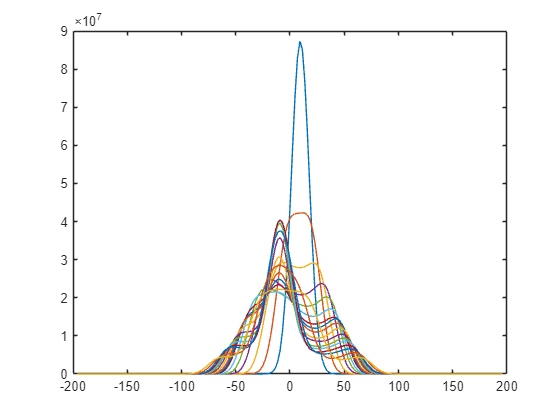

plot(xgrid,sumx)

Save

%making the data saved
constants = struct();
constants.I1_list = I1_list;
constants.I2_list = I2_list;
constants.lambda = lambda;
constants.MAX = MAX;
constants.tend = tend;
constants.tstep = tstep;
constants.vx_caused_tilted = vx_caused_tilted;
constants.w0 = w0;
constants.vel_pix=vel_pix;
constants.Dye_sigma=Dye_sigma;
constants.w0z = w0z;
constants.w0y = w0y;

data = struct();
data.xgrid=xgrid'
data.ygrid=ygrid'
data.img_matrix=img_matrix
data.sumx=sumx

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]
    ygrid: [173×1 double]

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}
          sumx: [173×17 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]
    ygrid: [173×1 double]

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}
          sumx: [173×17 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]
    ygrid: [173×1 double]

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}
          sumx: [173×17 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]

data = 다음 필드를 포함한 struct :
    xgrid: [173×1 double]
    ygrid: [173×1 double]

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}

data = 다음 필드를 포함한 struct :
         xgrid: [173×1 double]
         ygrid: [173×1 double]
    img_matrix: {17×1 cell}
          sumx: [173×17 double]

end
% filename=sprintf("data_%.0f_m_s.mat",tilt_ind)
% filename=sprintf("psw_%.1fum.mat",w0_list(data_ind))
filename = sprintf('a_eff_PSW_%.0f%.0f.mat',j_num,m_num)
tic
save(filename,'data','I1_list','I2_list','Cell_velocity','constants','x_matrix','Cell_alpha','Cell_x_matrix','Cell_y_matrix');
toc
end

filename = 'a_eff_PSW_00.mat'

경과 시간은 865.661793초입니다.


filename = 'a_eff_PSW_20.mat'

경과 시간은 849.826947초입니다.


filename = 'a_eff_PSW_21.mat'

경과 시간은 854.027503초입니다.


filename = 'a_eff_PSW_22.mat'

경과 시간은 855.759589초입니다.
